[test, train] = load_images();
img = reshape(test(1,:), 256, 256);

l = [0.599765 0.538732 0.091549 0.063380];

l = l * 256;
l

l =   153.5398  137.9154   23.4365   16.2253




size = 32;


a = round(l(1) - size);
b = round(l(1) + size);
c = round(l(2) - size);
d = round(l(2) + size);



p = [a b c d]

p =    122   186   106   170


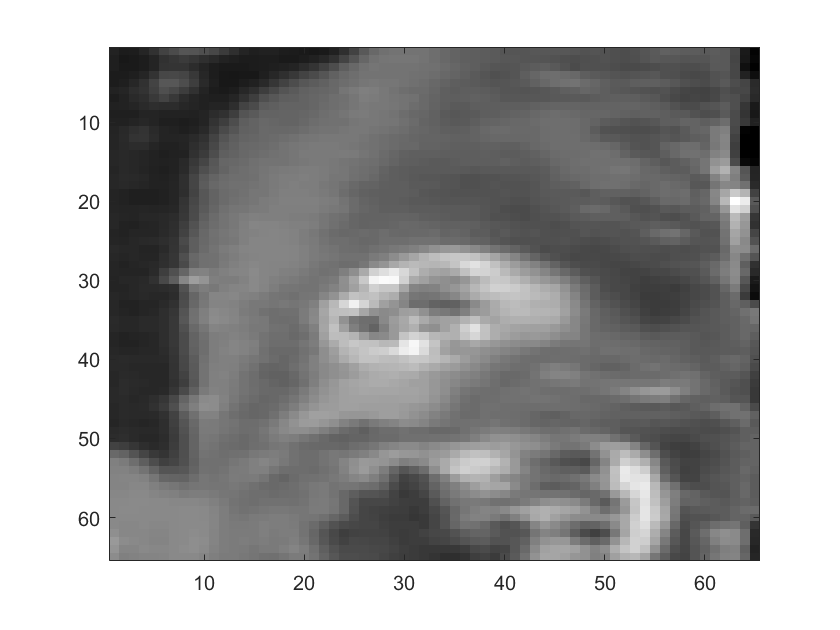

subimg = img(c:d,a:b);

clf
imagesc(subimg)

fileID = fopen('axial_t1wce_2_class\labels\test\00018_101.txt','r');
A = fscanf(fileID, "%c");
A

A =     '0 0.610915 0.661385 0.167840 0.134977
     0 0.599765 0.538732 0.091549 0.063380'

B = split(A,"\n")

B = 1×1 cell array
    {'0 0.610915 0.661385 0.167840 0.134977↵0 0.599765 0.538732 0.091549 0.063380'}

C = split(B," ")

C = 9×1 cell array
    {'0'          }
    {'0.610915'   }
    {'0.661385'   }
    {'0.167840'   }
    {'0.134977↵0'}
    {'0.599765'   }
    {'0.538732'   }
    {'0.091549'   }
    {'0.063380'   }

% str2num(B(2))
str2num(C{2})

ans = 0.6109

[test, train, test_labels, train_labels] = load_images();

Unable to perform assignment because the size of the left side is 1-by-65536 and the size of the right side is 1-by-16384.
Error in load_images (line 42)
    train(i, :) = img;